Load and test the new class labels

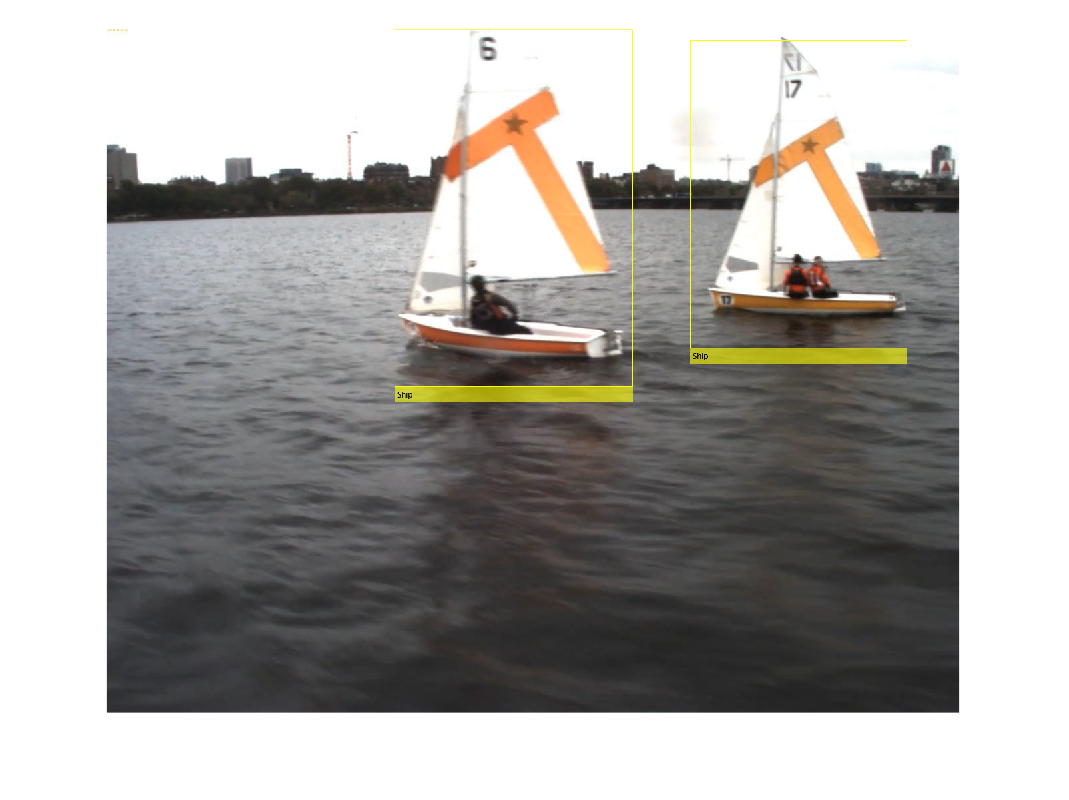

load gTruth_singleClass_ship.mat
data = gTruth_ship.LabelData;
bboxes = data.ship;
bboxes400 = bboxes{400};
Video = VideoReader('C:\Users\amird\OneDrive\Desktop\3rd_Year_VacWork\Maritime_Image_Analysis\Matlab docs for oceanography project\Datasets AIS promodromos\prodromos_2021_10_29_close_approach\videos\right_camera_VID.mp4');
frame400 = read(rightVideo, 400);
framebox = insertObjectAnnotation(frame400, 'rectangle', bboxes400, 'Ship');
imshow(framebox)

Now that the class labels have correctly been changed to just identify 'Ship', we need to retrain the detector.

[imList, boxLabels] = objectDetectorTrainingData(gTruth_ship, WriteLocation = 'Training_Set_Videos');


Write images extracted for training to folder: 
    Training_Set_Videos

Writing 158 images extracted from right_camera_VID.mp4...Completed.


gtData = combine(imList,boxLabels);
gtShuffled = shuffle(gtData);

   158



   158



disp(numpartitions(gtShuffled))
disp(numel(imList.Files))

Computing Input Normalization Statistics.
 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingYoloXLoss    ValidationYoloXLoss
    _____    _________    ___________    _________    _________________    ___________________
      1          1         00:00:09       0.0001           10.084                 4.213       
      1         50         00:03:49       0.0001           2.8408                             
      1         55         00:04:07       0.0001           2.1978                2.1219       
      2         100        00:07:36       0.0001           1.9916                             
      2         110        00:08:13       0.0001           1.8096                 1.785       
      3         150        00:10:57       0.0001           1.6382                      

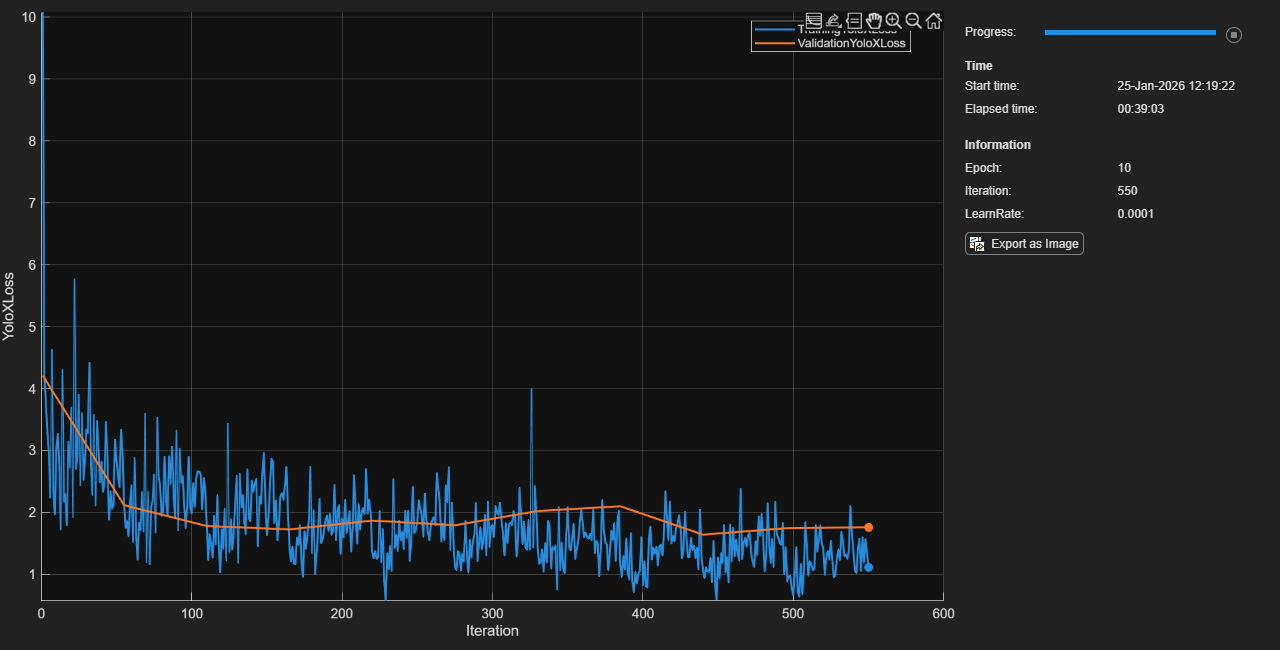

     10         550        00:38:45       0.0001           1.1223                 1.764       


ship_DetectorV1 =   yoloxObjectDetector with properties:

                 ClassNames: {'ship'}
                  InputSize: [640 512 3]
    NormalizationStatistics: [1×1 struct]
                  ModelName: 'tiny-coco'



numFiles = numel(imList.Files);
numTraining = floor(numFiles*0.7);
numValidation = floor(numFiles*0.1);
gtTrain = subset(gtShuffled,1:numTraining);
gtVal = subset(gtShuffled,(numTraining+1):(numTraining+numValidation));
gtTest = subset(gtShuffled, (numTraining + numValidation + 1):numFiles);
detector = yoloxObjectDetector("tiny-coco", gTruth_ship.LabelDefinitions.Name, InputSize=[640 512 3]);
options = trainingOptions('adam', MiniBatchSize = 2, MaxEpochs = 10, InitialLearnRate = 1e-4, ValidationData = gtVal, ValidationFrequency = floor(numTraining/2), ExecutionEnvironment = 'cpu', Verbose = true, Plots = 'training-progress');
ship_DetectorV1 = trainYOLOXObjectDetector(gtTrain, detector, options)

save('single_class_ShipDetector.mat', 'ship_DetectorV1')